**Name : Krish Singh**

**Roll: AID25072**

**AID Semester 2**

## **LAB EXCERCISE 9**

Question number 1 a:

syms x y
f = 3*x^2 + cos(4*x*y) - exp(2*y);
T = taylor(f, [x y], [2 1], 'Order', 4)

$$T = \cos\left(8\right)-{\mathrm{e}}^{2}+\frac{32\,\sin\left(8\right)\,{\left(x-2\right)}^{3}}{3}-\left(y-1\right)\,\left(2\,{\mathrm{e}}^{2}+8\,\sin\left(8\right)\right)-\left(4\,\sin\left(8\right)-12\right)\,\left(x-2\right)-{\left(y-1\right)}^{2}\,\left(32\,\cos\left(8\right)+2\,{\mathrm{e}}^{2}\right)-{\left(y-1\right)}^{3}\,\left(\frac{4\,{\mathrm{e}}^{2}}{3}-\frac{256\,\sin\left(8\right)}{3}\right)-\left(8\,\cos\left(8\right)-3\right)\,{\left(x-2\right)}^{2}-\left(x-2\right)\,\left(y-1\right)\,\left(32\,\cos\left(8\right)+4\,\sin\left(8\right)\right)-{\left(x-2\right)}^{2}\,\left(y-1\right)\,\left(16\,\cos\left(8\right)-64\,\sin\left(8\right)\right)-\left(x-2\right)\,{\left(y-1\right)}^{2}\,\left(32\,\cos\left(8\right)-128\,\sin\left(8\right)\right)+12$$

Question number 1 b:

syms x y

f = x^2 + y^2 + 1/(x^2 + y^2);

T = taylor(f, [x y], [3 5], 'Order', 4)

$$T = \frac{3465\,x}{578}+\frac{5775\,y}{578}+\frac{15\,\left(x-3\right)\,\left(y-5\right)}{4913}+\frac{19653\,{\left(x-3\right)}^{2}}{19652}+\frac{12\,{\left(x-3\right)}^{3}}{83521}+\frac{19685\,{\left(y-5\right)}^{2}}{19652}-\frac{20\,{\left(y-5\right)}^{3}}{83521}-\frac{25\,{\left(x-3\right)}^{2}\,\left(y-5\right)}{83521}-\frac{87\,\left(x-3\right)\,{\left(y-5\right)}^{2}}{83521}-\frac{1153}{34}$$

Question number 2 a:

clc; clear;
syms x y
% Define functions
f1 = (x - 3)^2 + y^2 - 9;
f2 = 3*y - x^2;

F = [f1; f2];

% Jacobian
J = jacobian(F, [x y]);

% Convert to function handles
F_func = matlabFunction(F, 'Vars', {[x y]});
J_func = matlabFunction(J, 'Vars', {[x y]});

% Initial guess
X = [5; 6];

% Newton Iteration (10 steps)
for i = 1:10
    X = X - J_func(X') \ F_func(X');
end

disp('Approximate Solution:')

Approximate Solution:


disp(X)

     3
     3



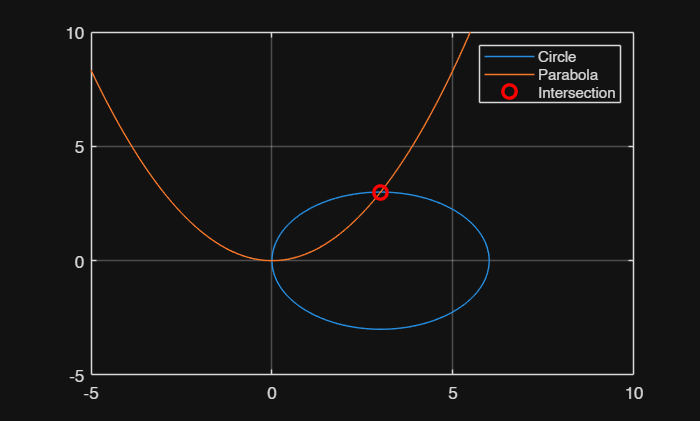

fimplicit(@(x,y) (x-3).^2 + y.^2 - 9, [-5 10 -5 10])
hold on
fimplicit(@(x,y) 3*y - x.^2, [-5 10 -5 10])

plot(X(1), X(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2)

legend('Circle','Parabola','Intersection')
grid on
hold off

Question number 2 b:

clc; clear;

syms x y

f1 = (x - 3)^2 + y^2 - 9;
f2 = 3*y - x^2;

F = [f1; f2];
J = jacobian(F, [x y]);

F_func = matlabFunction(F, 'Vars', {[x y]});
J_func = matlabFunction(J, 'Vars', {[x y]});

% NEW starting point
X = [-3; -1];

for i = 1:10
    X = X - J_func(X') \ F_func(X');
end

disp('Approximate Solution:')

Approximate Solution:


disp(X)

   1.0e-15 *

    0.1150
    0.0000



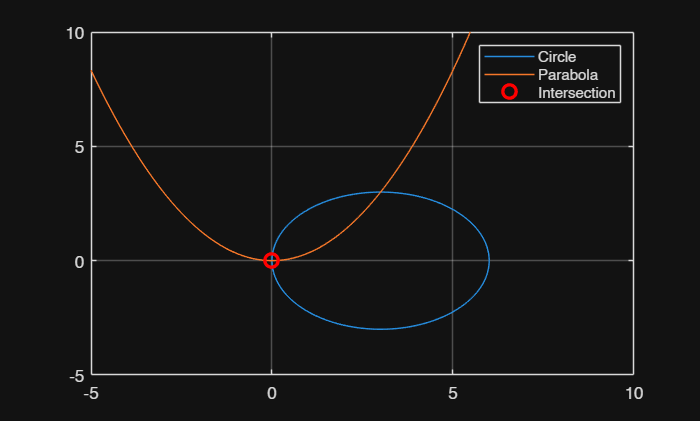


fimplicit(@(x,y) (x-3).^2 + y.^2 - 9, [-5 10 -5 10])
hold on
fimplicit(@(x,y) 3*y - x.^2, [-5 10 -5 10])

plot(X(1), X(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2)

legend('Circle','Parabola','Intersection')
grid on
hold off

Question number 2 c:

clc; clear;

syms x y

f1 = (x - 3)^2 + y^2 - 9;
f2 = x^2 + (y - 3)^2;

F = [f1; f2];
J = jacobian(F, [x y]);

F_func = matlabFunction(F, 'Vars', {[x y]});
J_func = matlabFunction(J, 'Vars', {[x y]});

% Initial guess
X = [9; -3];

for i = 1:10
    X = X - J_func(X') \ F_func(X');
end

disp('Approximate Solution:')

Approximate Solution:


disp(X)

   -0.0232
    1.4768



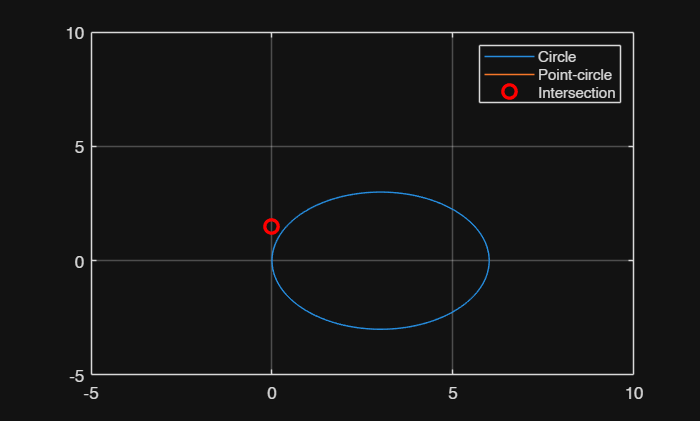


fimplicit(@(x,y) (x-3).^2 + y.^2 - 9, [-5 10 -5 10])
hold on
fimplicit(@(x,y) x.^2 + (y-3).^2, [-5 10 -5 10])

plot(X(1), X(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2)

legend('Circle','Point-circle','Intersection')
grid on
hold off

Question number 3:

clc; clear;

syms x1 x2 x3

% Define equations
f1 = -x1^2 + x2^2 + x1*x2*x3 - 1.34;
f2 = x1*x2 - x3^2 - 0.09;
f3 = exp(x1) - exp(x2) + x3 - 0.41;

F = [f1; f2; f3];

% Jacobian
J = jacobian(F, [x1 x2 x3]);

% Convert to function handles
F_func = matlabFunction(F, 'Vars', {[x1 x2 x3]});
J_func = matlabFunction(J, 'Vars', {[x1 x2 x3]});

% Initial guess
X = [1; 1; 1];

% Newton iterations
for i = 1:10
    X = X - J_func(X') \ F_func(X');
end

disp('Approximate Solution:')

Approximate Solution:


disp(X)

    0.9022
    1.1003
    0.9501



Question number 4:

clc; clear;

syms x1 x2 x3 x4

% Define function
f = (x1 + 10*x2)^2 + 5*(x3 - x4)^2 + x3^4 + 10*(x1 - x4)^4;

% Gradient and Hessian
grad_f = gradient(f, [x1 x2 x3 x4]);
H = hessian(f, [x1 x2 x3 x4]);

% Convert to functions
grad_func = matlabFunction(grad_f, 'Vars', {[x1 x2 x3 x4]});
H_func = matlabFunction(H, 'Vars', {[x1 x2 x3 x4]});

% Initial point
X = [3; -1; 0; 1];

% Newton iterations (3 steps only)
for i = 1:3
    X = X - H_func(X') \ grad_func(X');
end


disp('Approximate Minimizer:')

Approximate Minimizer:


disp(X)

    0.9259
   -0.0926
    0.3333
    0.3333



Question number 5:

clc; clear;

syms x y

% ---- DEFINE FUNCTION HERE ----
f = x^2 + y^2 + x*y;   % <-- change this for any problem

% Gradient and Hessian
grad_f = gradient(f, [x y]);
H = hessian(f, [x y]);

% Convert to function handles
grad_func = matlabFunction(grad_f, 'Vars', {[x y]});
H_func = matlabFunction(H, 'Vars', {[x y]});

% Initial guess
X = [1; 1];   % <-- change as needed

% Number of iterations
n = 10;

for i = 1:n
    X = X - H_func(X') \ grad_func(X');
end

disp('Minimum occurs at:')

Minimum occurs at:


disp(X)

     0
     0



Question number 6:

clc; clear;

% ---- DEFINE FUNCTION ----
f = @(x,y) x^2 + y^2 + x*y;   % change this as needed

% Initial guess
X = [1; 1];

% Parameters
n = 10;        % iterations
h = 1e-5;      % small step for finite difference

for k = 1:n
    
    x = X(1);
    y = X(2);
    
    % ---- Gradient (central difference) ----
    df_dx = (f(x+h,y) - f(x-h,y)) / (2*h);
    df_dy = (f(x,y+h) - f(x,y-h)) / (2*h);
    
    grad = [df_dx; df_dy];
    
    % ---- Hessian (finite difference) ----
    d2f_dx2 = (f(x+h,y) - 2*f(x,y) + f(x-h,y)) / (h^2);
    d2f_dy2 = (f(x,y+h) - 2*f(x,y) + f(x,y-h)) / (h^2);
    
    d2f_dxdy = (f(x+h,y+h) - f(x+h,y-h) - f(x-h,y+h) + f(x-h,y-h)) / (4*h^2);
    
    H = [d2f_dx2, d2f_dxdy;
         d2f_dxdy, d2f_dy2];
    
    % ---- Newton Update ----
    X = X - H \ grad;
end

disp('Approximate Minimum:')

Approximate Minimum:


disp(X)

     0
     0

